## initialize environment

defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 6 - SGNs');


%load WT + MRS2500 @ room temp
base = '.\Data\WT_MRS2500\';
%filename, baseline start (sec), end, drug start, end
 files = {
            %WT + MRS25000
            '15719003.abf',0,600,900,1500
            '15723000.abf',0,600,900,1500
            '15723002.abf',0,600,900,1500
            '15723003.abf',0,600,900,1500
            '15723006.abf',60,660,960,1560
            '15724007.abf',0,600,900,1500
            '15725007.abf',0,600,900,1500
            };
        
ISI_data = loadSGNs(base,files);

opening .\Data\WT_MRS2500\15725007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1808.8 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 552 MB


opening .\Data\WT_MRS2500\15724007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1930.4 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB


opening .\Data\WT_MRS2500\15723006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2010.4 s ~ 34 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 614 MB


opening .\Data\WT_MRS2500\15723003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1884.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 575 MB


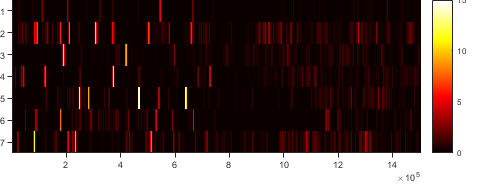

%WT + MRS2500 @ room temp heat map
load('.\Data\WT_MRS2500\group_ISIs.mat');

time_raster = 0:.001:1500;
conv_filt = ones(5000,1); %10000ms/10s window for moving average
ISI_heat = [];
ISI_heat_2 = [];

for i=1:size(ISI_data,1)
    signal_raster = zeros(size(time_raster));
    signal_raster(int32(ISI_data{i,5})) = 1;
    mov_avg = conv(conv_filt,signal_raster);
    ISI_heat(i,:) = mov_avg;
end

%%
figure;
colormap('hot');
imagesc(ISI_heat/5,[0 15]);
colorbar;
figQuality(gcf,gca,[5 2]);
export_fig('.\EPS Panels\WT_MRS_SGN.eps','-eps');

%load WT and KO ISIs
files = {
            '15719003.abf',0,600,'WT'
            '15723000.abf',0,600,'WT'
            '15723002.abf',0,600,'WT'
            '15723003.abf',0,600,'WT'
            '15723006.abf',60,660,'WT'
            '15724007.abf',0,600,'WT'
            '15725007.abf',0,600,'WT'
            '15822000.abf',0,600,'WT'
            '15822002.abf',60,660,'WT'
            '15822004.abf',0,600, 'WT'
         }; 
KOfiles = {  
            '15724000.abf',30,630,'KO'
             '15724001.abf',0,600,'KO'
             '15724002.abf',0,600,'KO'
             '15724004.abf',0,600,'KO'
             '15724005.abf',0,600,'KO'
             '15725000.abf',0,600,'KO'
             '15725005.abf',0,600,'KO'
             '15725006.abf',0,600,'KO'
             '15905000.abf',0,600,'KO'
             '15905002.abf',0,600, 'KO'
             '15905004.abf',0,600, 'KO' 
         };
     
base = '.\Data\WT\';
ISI_data = loadSGNs(base,files);
base = '.\Data\P2ry1 KO\';
KO_ISI_data = loadSGNs(base,KOfiles);

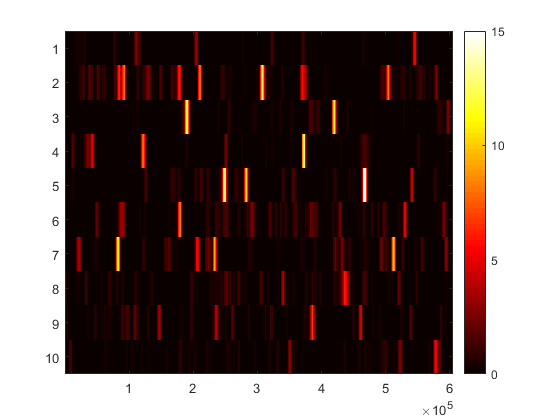

%plot heatmaps
load('.\Data\WT\WT_group_ISIs.mat');
heatmapFromISIs(ISI_data);

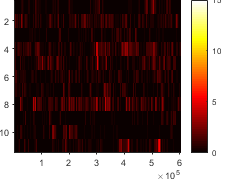

load('.\Data\P2ry1 KO\KO_group_ISIs.mat');
heatmapFromISIs(KO_ISI_data);
figQuality(gcf,gca,[2.5 2]);
export_fig('.\EPS Panels\KO_SGN.eps','-eps');

opening .\Data\WT_Thapsigargin\15731007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 906.4 s ~ 15 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 277 MB


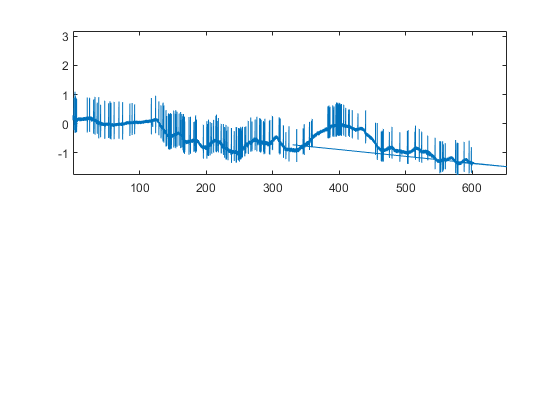

opening .\Data\WT_Thapsigargin\15731004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1005.2 s ~ 17 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 307 MB


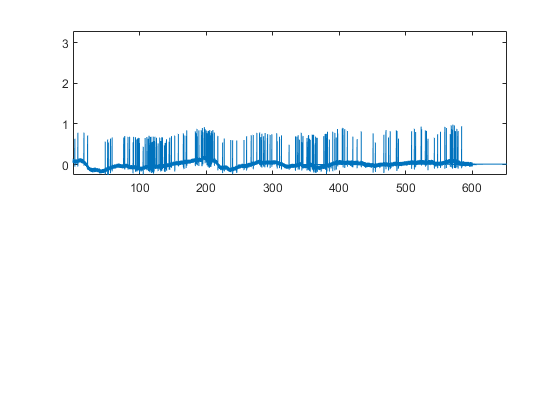

opening .\Data\WT_Thapsigargin\15731003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 901.3 s ~ 15 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 275 MB


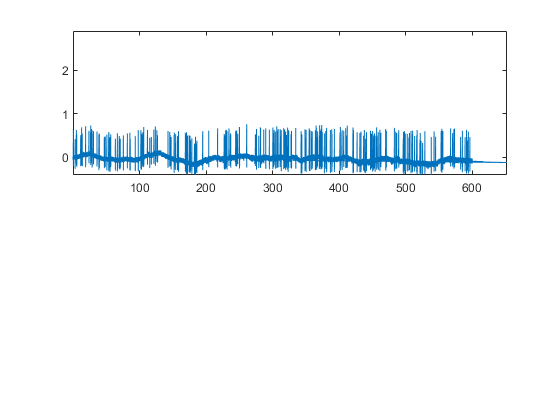

opening .\Data\WT_Thapsigargin\15731000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1432.3 s ~ 24 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 437 MB


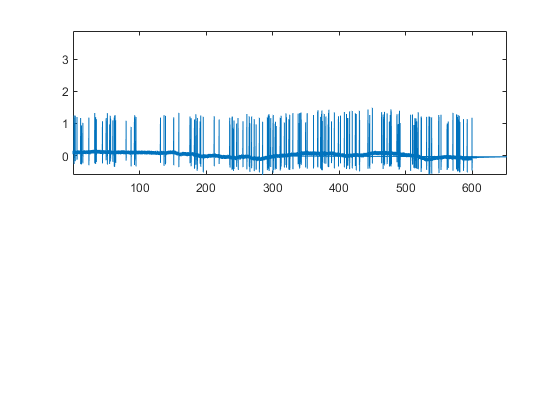

%load thapsi
%thapsi
files = {
             '15731000.abf',300,900,'Thapsi'
             '15731003.abf',0,600,'Thapsi'
             '15731004.abf',60,660,'Thapsi'
             '15731007.abf',0,600,'Thapsi'
         };
     
base = '.\Data\WT_Thapsigargin\';
thapsi_ISI_data = loadSGNs(base,files);

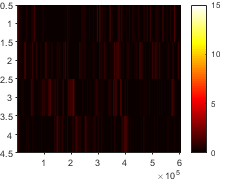

heatmapFromISIs(thapsi_ISI_data);
figQuality(gcf,gca,[2.5 2]);
export_fig('.\EPS Panels\thapsi_SGN.eps','-eps');

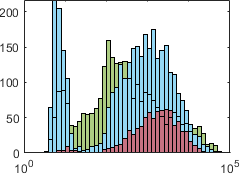

%WT KO MRS Thapsi
WT_ISIs = [];
for i = 1:size(ISI_data)
    WT_ISIs = [WT_ISIs; ISI_data{i,4}];
end

KO_ISIs = [];
for i = 1:size(KO_ISI_data)
    KO_ISIs = [KO_ISIs; KO_ISI_data{i,4}];
end

thapsi_ISIs = [];
for i = 1:size(thapsi_ISI_data)
    thapsi_ISIs = [thapsi_ISIs; thapsi_ISI_data{i,4}];
end


edges = 10.^(-1:0.1:6);
histogram(WT_ISIs,edges); 
hold on;
histogram(KO_ISIs,edges);
histogram(thapsi_ISIs,edges);
%hold off;
set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);    

## More detailed analysis

## Analyze SGNs

%
miniburst_thr = 20; %time must be below XX ms to be considered a miniburst
burst_thr = 1000; %time must be below XX ms to be condidered a burst
           
analyze data
WT_SGN_paths = loadFileList('.\Data\WT\*.abf');
WT_times = [ 0,600; 0,600; 0,600; 0,600; 60,660; 0,600; 0,600; 0,600; 60,660; 0,600]; 

for i = 1:size(WT_SGN_paths,1)
    [b_spikes, b_ISIs, b_locs] = SGN_ISI(WT_SGN_paths{i},WT_times(i,:));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
end
 
P2ry1KO_SGN_paths = loadFileList('.\Data\P2ry1 KO\*.abf');
KO_times = [ 30,630; 0,600; 0,600; 0,600; 0,600; 0,600; 0,600; 0,600; 0,600; 0,600; 0,600]; 

for i = 1:size(P2ry1KO_SGN_paths,1)
    [b_spikes, b_ISIs, b_locs] = SGN_ISI(P2ry1KO_SGN_paths{i},KO_times(i,:));
        [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
     [fp, name, ext] = fileparts(P2ry1KO_SGN_paths{i})
     save([fp '\' name '_spikes.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1832.2 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 559 MB
Baseline Spikes (Freq):182.000000 (0.000303)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15724000'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724001.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1800.1 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 549 MB
Baseline Spikes (Freq):402.000000 (0.000670)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15724001'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1801.2 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB
Baseline Spikes (Freq):141.000000 (0.000235)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15724002'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1800.4 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 549 MB
Baseline Spikes (Freq):525.000000 (0.000875)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15724004'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724005.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1896.5 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 579 MB
Baseline Spikes (Freq):408.000000 (0.000680)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15724005'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1929.5 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB
Baseline Spikes (Freq):278.000000 (0.000463)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15725000'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725005.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1225.8 s ~ 20 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 374 MB
Baseline Spikes (Freq):235.000000 (0.000392)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15725005'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1835.1 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 560 MB
Baseline Spikes (Freq):583.000000 (0.000972)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15725006'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1801.1 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB
Baseline Spikes (Freq):139.000000 (0.000232)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15905000'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1804.0 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 551 MB
Baseline Spikes (Freq):190.000000 (0.000317)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15905002'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1845.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 563 MB
Baseline Spikes (Freq):293.000000 (0.000488)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO'

name = '15905004'

ext = '.abf'

edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.num_bursts; 
    WT_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    WT_burstDur(i,1) =  bursts.burst_dur;
    WT_spikeCounts(i,1) = b_spikes/600;
    WT_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

KO_SGN_data = loadFileList('.\Data\P2ry1 KO\*_spikes.mat');
KO_numBursts = []; KO_spikesPerBurst = []; KO_burstDur = []; KO_spikeCounts = []; KO_binCounts = [];
KO_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(KO_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    KO_binCounts(i,:) = h;
    KO_numBursts(i,1) = bursts.num_bursts; 
    KO_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    KO_burstDur(i,1) =  bursts.burst_dur;
    KO_spikeCounts(i,1) = b_spikes/600;
    KO_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

 dim = [1 1.5]

dim =     1.0000    1.5000


 [h, p] = compare2(WT_numBursts/10,KO_numBursts/10,{'WT', 'P2ry1 KO'}, 'Bursts per minute', dim);

   1.6227e-04



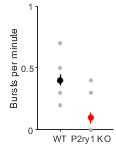

 ylim([0 1]);
 yticks([0:.5:1]);
 figQuality(gcf,gca,dim)
 export_fig('.\EPS Panels\burstNum.eps',gcf);  

    
[h, p] = compare2(WT_spikesPerBurst,KO_spikesPerBurst,{'WT', 'P2ry1 KO'}, 'Spikes per burst', dim);

    0.0484



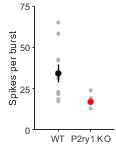

ylim([0 75]);
yticks([0:25:75]);   
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\spikesPerBurst.eps',gcf);

    
[h, p] = compare2(WT_burstDur/1000,KO_burstDur/1000,{'WT', 'P2ry1 KO'}, 'Burst duration (s)', dim);

    0.8358



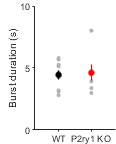

ylim([0 10]);
yticks([0:5:10]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\burstDuration.eps',gcf);


[h, p] = compare2(WT_CVISI,KO_CVISI,{'WT', 'P2ry1 KO'}, 'CVISI', dim);

    0.0011



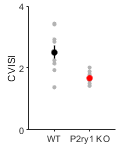

ylim([0 4]);
yticks([0:2:4]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\CVISIs.eps',gcf);

    

[h, p] = compare2(WT_spikeCounts, KO_spikeCounts,{'WT', 'P2ry1KO'}, 'Spike frequency (Hz)', dim);

    0.5545



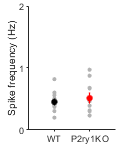

ylim([0 2])
yticks([0:1:2])
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\spikeFreq.eps',gcf);

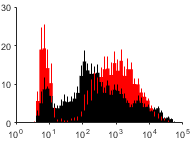

    

figure; 
histogram('BinCounts', mean(KO_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none','FaceColor','r'); hold on;
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none', 'FaceColor','k'); hold on;

set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
errorbar(edges2(1:end-1),mean(KO_binCounts,1),sterr(KO_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\P2ry1_ISIhisto.eps',gcf);

%Control + MRS
%
miniburst_thr = 20; %time must be below XX ms to be considered a miniburst
burst_thr = 1000; %time must be below XX ms to be condidered a burst
           
WT_SGN_paths = loadFileList('.\Data\WT_MRS2500\*.abf');
MRS_times = [0,600,900,1500; 0,600,900,1500; 0,600,900,1500; 0,600,900,1500; 60,660,960,1560; 0,600,900,1500; 0,600,900,1500];

for i = 1:size(WT_SGN_paths,1)
    [b_spikes, b_ISIs, b_locs] = SGN_ISI(WT_SGN_paths{i},MRS_times(i,1:2));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
    
    [b_spikes, b_ISIs, b_locs] = SGN_ISI(WT_SGN_paths{i},MRS_times(i,3:4));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes_MRS.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15719003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1750.6 s ~ 29 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 534 MB
Baseline Spikes (Freq):120.000000 (0.000200)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15719003'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15719003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1750.6 s ~ 29 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 534 MB
Baseline Spikes (Freq):117.000000 (0.000195)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15719003'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1677.6 s ~ 28 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 512 MB
Baseline Spikes (Freq):492.000000 (0.000820)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723000'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1677.6 s ~ 28 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 512 MB
Baseline Spikes (Freq):424.000000 (0.000707)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723000'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1802.5 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB
Baseline Spikes (Freq):223.000000 (0.000372)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723002'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1802.5 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB
Baseline Spikes (Freq):256.000000 (0.000427)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723002'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1884.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 575 MB
Baseline Spikes (Freq):229.000000 (0.000382)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723003'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1884.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 575 MB
Baseline Spikes (Freq):265.000000 (0.000442)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723003'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2010.4 s ~ 34 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 614 MB
Baseline Spikes (Freq):336.000000 (0.000560)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723006'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2010.4 s ~ 34 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 614 MB
Baseline Spikes (Freq):241.000000 (0.000402)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15723006'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15724007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1930.4 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB
Baseline Spikes (Freq):304.000000 (0.000507)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15724007'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15724007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1930.4 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB
Baseline Spikes (Freq):144.000000 (0.000240)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15724007'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15725007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1808.8 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 552 MB
Baseline Spikes (Freq):363.000000 (0.000605)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15725007'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15725007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1808.8 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 552 MB
Baseline Spikes (Freq):416.000000 (0.000693)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500'

name = '15725007'

ext = '.abf'

edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT_MRS2500\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISI = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.num_bursts; 
    WT_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    WT_burstDur(i,1) =  bursts.burst_dur;
    WT_spikeCounts(i,1) = b_spikes/600;
    WT_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

MRS_SGN_data = loadFileList('.\Data\WT_MRS2500\*_spikes_MRS.mat');
MRS_numBursts = []; MRS_spikesPerBurst = []; MRS_burstDur = []; MRS_spikeCounts = []; MRS_binCounts = [];
MRS_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(MRS_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    MRS_binCounts(i,:) = h;
    MRS_numBursts(i,1) = bursts.num_bursts; 
    MRS_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    MRS_burstDur(i,1) =  bursts.burst_dur;
    MRS_spikeCounts(i,1) = b_spikes/600;
    MRS_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

 dim = [1 1.5]

dim =     1.0000    1.5000


 [h, p] = compare2P(WT_numBursts/10,MRS_numBursts/10,{'WT', 'MRS'}, 'Bursts per minute', dim);

    0.0061



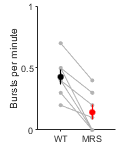

 ylim([0 1]);
 yticks([0:.5:1]);
 figQuality(gcf,gca,dim)
 export_fig('.\EPS Panels\MRS_burstNum.eps',gcf);  

    
[h, p] = compare2P(WT_spikesPerBurst,MRS_spikesPerBurst,{'WT', 'MRS'}, 'Spikes per burst', dim);

    0.0219



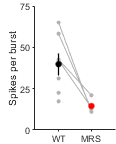

ylim([0 75]);
yticks([0:25:75]);   
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikesPerBurst.eps',gcf);

    
[h, p] = compare2P(WT_burstDur/1000,MRS_burstDur/1000,{'WT', 'MRS'}, 'Burst duration (s)', dim);

    0.3602



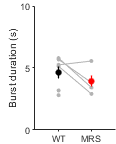

ylim([0 10]);
yticks([0:5:10]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_burstDuration.eps',gcf);


[h, p] = compare2P(WT_CVISI,MRS_CVISI,{'WT', 'MRS'}, 'CVISI', dim);

   1.9144e-04



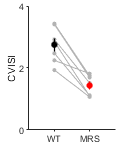

ylim([0 4]);
yticks([0:2:4]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_CVISIs.eps',gcf);

    

[h, p] = compare2P(WT_spikeCounts, MRS_spikeCounts,{'WT', 'MRS'}, 'Spike frequency (Hz)', dim);

    0.6557



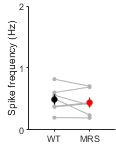

ylim([0 2])
yticks([0:1:2])
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikeFreq.eps',gcf);

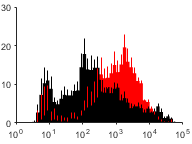

    

figure; 
histogram('BinCounts', mean(MRS_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none','FaceColor','r'); hold on;
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none', 'FaceColor','k'); hold on;

set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
errorbar(edges2(1:end-1),mean(MRS_binCounts,1),sterr(MRS_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\MRS_ISIhisto.eps',gcf);

% MRS Spiking
dname = ['.\Data\WT_MRS_SGN_WC_RoomTemp'];
temp = dir(dname);
folderlist = [temp(3:end)];

        fileList = loadFileList([folderlist(1).folder  '\' folderlist(1).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_RoomTemp\180808_Cell2\18808021_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 916 MB


        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+8*60+8*60],[550 550],'Color','k');
        line([360+8*60 360+8*60+8*60],[590 590],'Color','k');
        xlim([0 2000]);
        ylim([-2000 300]);
        export_fig(['.\EPS Panels\Examples\ouabain_MRS_' num2str(i) '.eps'])

% MRS Spiking
dname = ['.\Data\WT_MRS_SGN_WC_PhysTemp'];
temp = dir(dname);
folderlist = [temp(3:end)];

        fileList = loadFileList([folderlist(1).folder  '\' folderlist(1).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1\18808011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1455.3 s ~ 24 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 555 MB


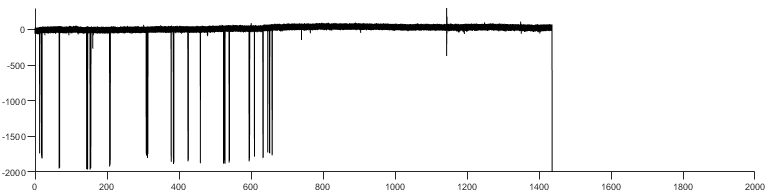

        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+8*60+8*60],[550 550],'Color','k');
        line([360+8*60 360+8*60+8*60],[590 590],'Color','k');
        xlim([0 2000]);
        ylim([-2000 300]);
        export_fig(['.\EPS Panels\Examples\PT_MRS_' num2str(i) '.eps'])

function heatmapFromISIs(ISI_data)

time_raster = 0:.001:600;
conv_filt = ones(5000,1); %10000ms/10s window for moving average
ISI_heat = [];

for i=1:size(ISI_data,1)
    signal_raster = zeros(size(time_raster));
    signal_raster(int32(ISI_data{i,5})) = 1;
    mov_avg = conv(conv_filt,signal_raster);
    ISI_heat(i,:) = mov_avg;
end

%%
figure;
colormap('hot');
imagesc(ISI_heat/5,[0 15]);
colorbar;

end


%%
%% 
%%



%%



